# Robot Control Template Using ROS

# RoboCup Virtual Robot Manipulation Challenge

Copyright 2021 The MathWorks, Inc

This MATLAB Live Script provides a reference for interacting with the environment for the RoboCup Virtual Manipulation Challenge. This template shows how to use features from [ROS Toolbox](https://www.mathworks.com/help/ros/index.html) and [Robotics System Toolbox](https://www.mathworks.com/help/robotics/index.html) to control the robot manipulator and obtain sensor information. Please note that any movement from the environment objects must be the outcome of a physical interaction within the environment. 

## Setup the Virtual Simulation Environment

[**Instructions to setup MathWorks provided virtual machine**](https://www.mathworks.com/support/product/robotics/ros2-vm-installation-instructions-v3.html)

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the MathWorks RoboCup Manipulation Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

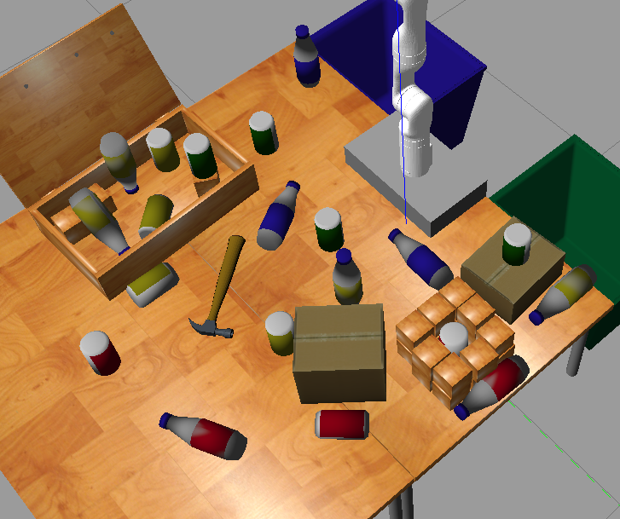

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

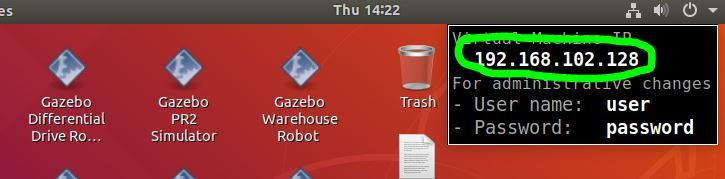

rosIP = "192.168.209.128"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_31468 with NodeURI http://192.168.209.1:33703/


%rosinit(rosIP,'NodeHost','192.168.1.213') % Try specifying node host IP in case that there are multiple network adapters

## Load Robot Model 

Load the rigid body tree "robot" from a saved mat file. Rigid Body trees are used in MATLAB to access manipulation features such as forward/inverse kinematics and dynamics and using motion planners. For more information visit the documentation for [Robotic Manipulation](https://www.mathworks.com/help/robotics/manipulators.html) and other [examples from Robotics System Toolbox](https://www.mathworks.com/help/robotics/examples.html).

load('exampleHelperKINOVAGen3GripperROSGazebo.mat');

## Initialize Robot and Start Simulator

#### Set initial robot configuration

RoboCupManipulation_setInitialConfig; % DO NOT MODIFY

#### Unpause GAZEBO physics.

Unpausing the Gazebo simulation is necessary to make sure the environment physics are active.

physicsClient = rossvcclient('gazebo/unpause_physics');
physicsResp = call(physicsClient,'Timeout',3);

## Control Gripper Position using ROS Action Client

#### Setup ROS Subscriber and Action Client for Joint Control

jointSub = rossubscriber('/my_gen3/joint_states');
[trajAct,trajGoal] = rosactionclient( '/my_gen3/gen3_joint_trajectory_controller/follow_joint_trajectory');

#### Define Gripper Pose

This section defines the desired gripper location and orientation using a homogeneous transformation. [Learn more about homogeneous transform here.](https://www.mathworks.com/help/robotics/coordinate-system-transformations.html)

gripperX = 0.5;
gripperY = 0.06;
gripperZ = 0.23;
gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = 0; % radians
gripperRotationY = 3*pi/4; % radians
gripperRotationZ = pi/2; % radians
desiredGripperPose = trvec2tform(gripperTranslation)*axang2tform([1 0 0 gripperRotationX])*axang2tform([0 1 0 gripperRotationY])*axang2tform([0 0 1 gripperRotationZ]);

#### Compute joint trajectory 

This section computes indivdual trajectories for each robot joint to move to the desired gripper position using inverse kinematics. In order to compute a feasible configuration the current robot configuration is used within the provided utility.

jointMsg = receive(jointSub,2);
currentRobotJConfig =  jointMsg.Position(2:8);
[q,qd,qdd,trajTimes] = RoboCupManipulation_computeTrajectory(currentRobotJConfig, desiredGripperPose, robot, 'gripper', 4);

#### Package and send the joint trajectory 

This section uses a provided utility to package the generated trajectory as the respective ROS message necessary to call the available ROS Action Server.

trajGoal = RoboCupManipulation_packageJointTrajectory(trajGoal,q,qd,qdd,trajTimes);
waitForServer(trajAct);
sendGoal(trajAct,trajGoal)

## Control Gripper Using ROS Action Client

[gripAct,gripGoal] = rosactionclient('/my_gen3/custom_gripper_controller/gripper_cmd');
gripperCommand = rosmessage('control_msgs/GripperCommand');
gripperCommand.Position = 0; % 0.04 fully closed, 0 fully open
gripperCommand.MaxEffort = 500;
gripGoal.Command = gripperCommand;
waitForServer(gripAct);
sendGoal(gripAct,gripGoal)

## Receive Camera Image Using ROS Subscriber

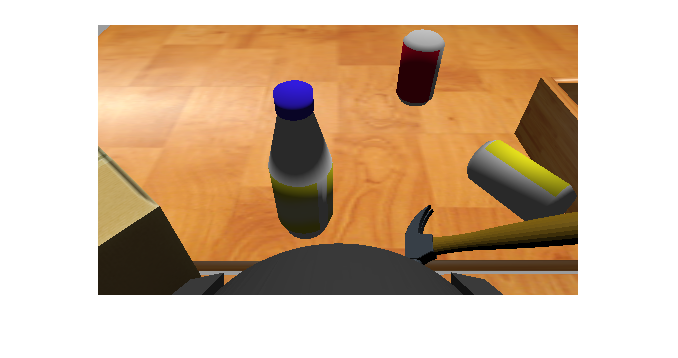

rgbImgSub = rossubscriber('/camera/color/image_raw');
curImage = receive(rgbImgSub);
rgbImg = readImage(rgbImgSub.LatestMessage); 
% imwrite(rgbImg,"/home/dennis/Desktop/robocup-robot-manipulation-challenge/src/models/can01.png")
imshow(rgbImg)

% bottle_or_can(rgbImg) 
% bottle_or_can(rgbImg)





## Receive Depth Image Using ROS Subscriber

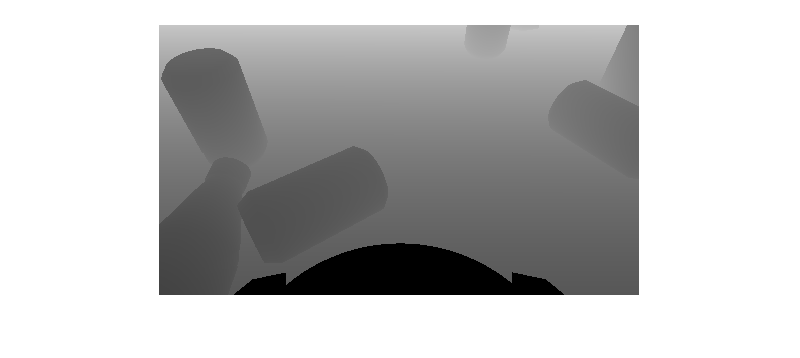

rgbDptSub = rossubscriber('/camera/depth/image_raw');
curDepth = receive(rgbDptSub);
depthImg = readImage(rgbDptSub.LatestMessage); 
imshow(depthImg)  

img_g = 270×480 single matrix
    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7740    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741    0.7741
    0.7703    0.7703    0.7703    0.7703    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7705    0.7705    0.7705    0.7705    0.7705    0.7705    0.7705    0.7705    0.770

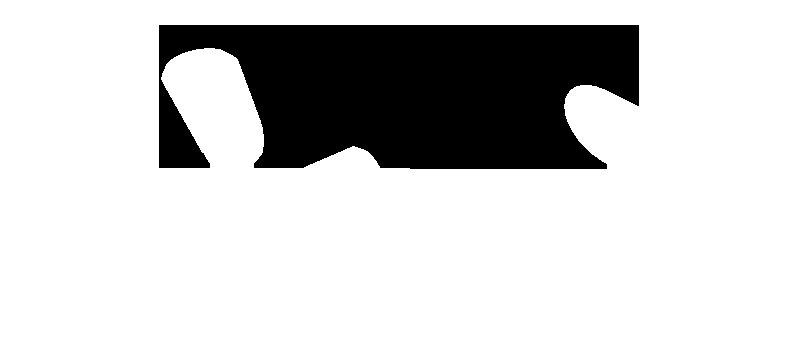

ris = 270×480 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

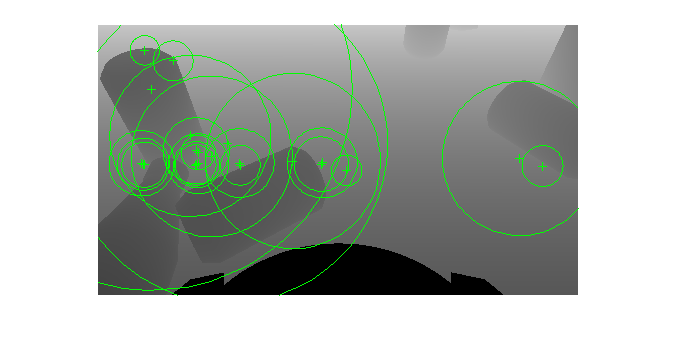

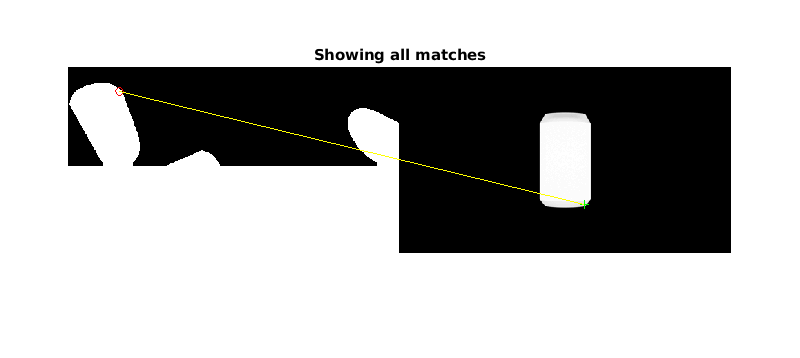

bottle_or_can(depthImg)